# **Week1 - Initial Optical Channel**

The code below implements a preliminary model of an optical channel without DSPs and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using a chosen modulation format - QPSK or 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An AWGN adder

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

% Generating symbols based on random input source bits
sourceBits = randi([0 1], NBits, NSequences); % Vector of source bits
[sourceBits, symbols] = SymbolGeneration('QPSK', inputBits, true, 20)

sourceBits =      0
     1
     1
     0
     1
     0
     0
     1
     1
     1


symbols =   -0.7071 + 0.7071i
   0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
   0.7071 - 0.7071i


### Pulse Shaping

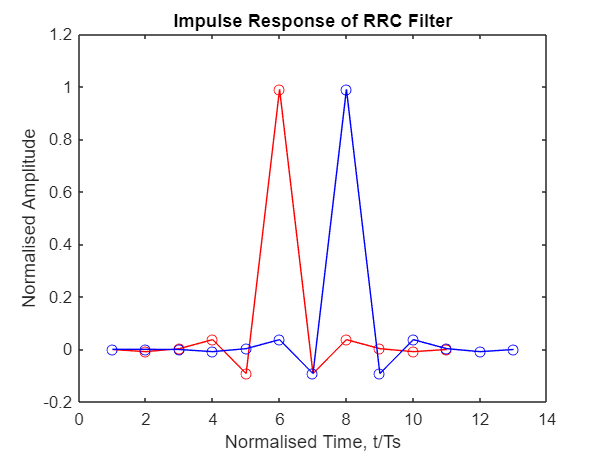

% Graphical output of RRC filter shape
filterResponse = rcosdesign(0.5, 10, 1);
plot(filterResponse, "r-o");
title('Impulse Response of RRC Filter');
xlabel('Normalised Time, t/Ts');
ylabel('Normalised Amplitude');
ylim([-0.2, 1.2]);
hold on;
plot([0 0 filterResponse], "b-o");
hold off;

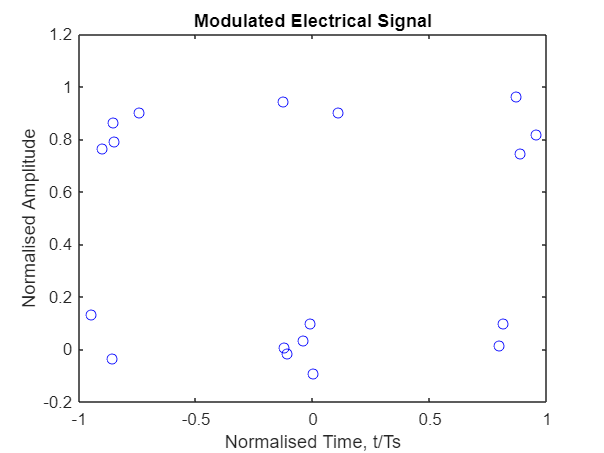


% Generating a signal based on the symbols created in the previous section
modulatedSignal = PulseShaping(symbols, 2, size(symbols, 1), 0.5);
plot(modulatedSignal, "bo")
title('Modulated Electrical Signal')
xlabel('Normalised Time, t/Ts')
ylabel('Normalised Amplitude')
ylim([-0.2, 1.2])

### IQM Modulation

% Initialising laser parameters
centreLambda = 299792458*2.5;
lineWidth = 0;
laserPw_dBm = 0;
NSymb = 20;
SpS = 1;
Rs = 5;
T = 1/(SpS*Rs);
t= [0:1:NSymb*SpS - 1]*T

t =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000


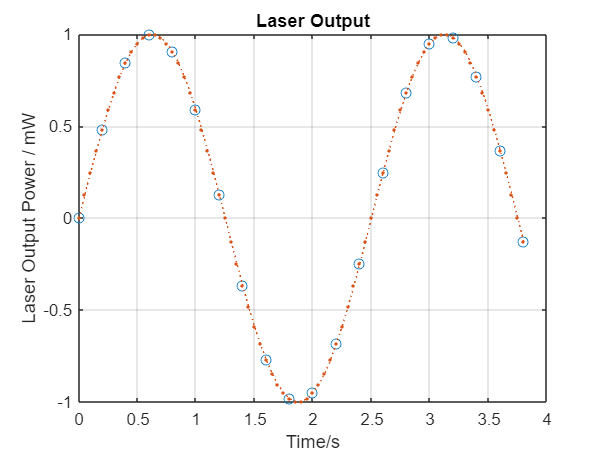


% Generating output from laser
[laserOutR,laserOutC] = LaserModified(laserPw_dBm, centreLambda, lineWidth, SpS, Rs, NSymb, 1);

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
E_interp = interp1(t, laserOutR, t_interp, "spline");
plot(t, laserOutR, "o", t_interp, E_interp,":.");
title("Laser Output")
xlabel("Time/s")
ylabel("Laser Output Power / mW")
grid on

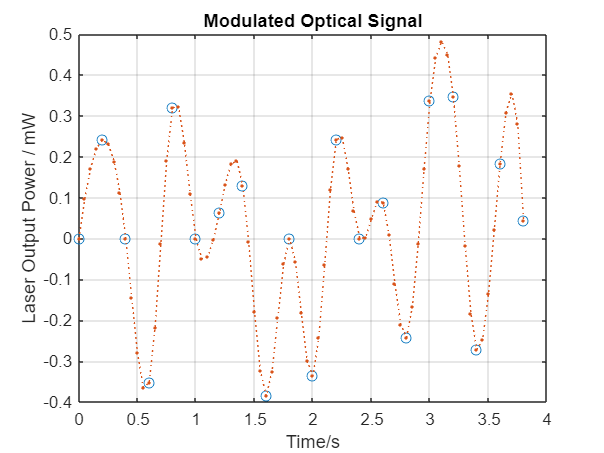


% Intialising IQM parameters
Vpi = pi/2; % Voltge required to change phase of E-field by pi
Vscale = pi/4;
vI = Vscale*randi([0,3], NSymb*SpS, 1);
vQ = Vscale*randi([0,3], NSymb*SpS, 1);

modOpticSig = IQModulatorModified(vI, vQ, laserOutR, Vpi);

% Visualising modulated optic signal
modOpticSig_interp = interp1(t, modOpticSig, t_interp, "spline");
plot(t, modOpticSig, "o", t_interp, modOpticSig_interp,":.");
title("Modulated Optical Signal")
xlabel("Time/s")
ylabel("Laser Output Power / mW")
grid on

## Optical Channel

### Adding AWGN

### Adding CD

## Optical Receiver

% Optical Receiver Parameters








